# Control ELCN304 Project

By

Andew Amir Ramses

Nour El-Din Khaled

Omar Tarek Ahmed Mohamed Ali Amer 1180004

Youssef Alaa

## Question 1

### Requirement 1

Due to the amplifier, we have


$$V_a =50\;V_i \;\;\;\;\;\;\;\left(0\right)$$


And by writing the KVL equation on the motor circuit we get


$$V_a ={\textrm{Ri}}_a +e_{b\;} \;\;\;\;\;\;\left(1\right)$$



$$\textrm{Where}\;e_b \;\textrm{is}\;\textrm{the}\;\textrm{back}\;\textrm{emf}\ldotp$$


We know that the back emf is proportional to the angular velocity of the motor, this yields equation no. 2


$$V_a ={\textrm{Ri}}_a +K_b \dot{\theta} \;\;\;\;\;\left(2\right)$$


And from Newton's second law we can obtain equation no.3


$$J\ddot{\theta} =K_T i_a \;\;\;\;\;\;\left(3\right)$$


And from the given equations:


$$\begin{array}{l}
q_o =51\;h\left(t\right)\;\;\;\;\;\;\left(4\right)\\
q_1 =82\;\theta \;\;\;\;\;\;\;\;\;\;\;\left(5\right)
\end{array}$$


And if we apply the tank equations, we get equations no. 6 and 7


$$\begin{array}{l}
q_1 -q_o =A\;\frac{d}{\mathrm{d}t}h\;\;\;\;\;\;\left(6\right)\\
h=q_0 \;R_v \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(7\right)
\end{array}$$



$$\textrm{Where}\;R_v \;\textrm{is}\;\textrm{the}\;\textrm{resistance}\;\textrm{value}\;\textrm{of}\;\textrm{the}\;\textrm{valve}\ldotp$$


Plugging equation no.5 into equation no.6 gives us


$$82\;\theta -q_o =A\;\frac{d}{\mathrm{d}t}h\;\;\;\;\;\;\left(8\right)$$


The SSR equations take the form


$$\begin{array}{l}
A\underline{x} +B\underline{u\;} =\underline{\dot{x} } \;\;\;\;\;\;\left(9\right)\\
C\underline{x} +D\underline{u} =\underline{y} \;\;\;\;\left(10\right)
\end{array}$$


We choose the position of the shaft as our first state, its angular velocity as the second, and the level of the tank as the third state. The input of the system is $V_i$ and the output is $h\left(t\right)$.


$$\begin{array}{l}
x_1 =\theta \\
x_2 =\dot{\theta} \\
x_3 =h\left(t\right)
\end{array}$$


We now get the state equations:


$$\dot{x} {\;}_1 =x_2 \;\;\;\;\;\;\left(11\right)$$


From equation no.3


$$J\ddot{\theta} =K_T i_a \;$$

$$\rightarrow$$

$$\dot{x} {\;}_2 =\frac{K_T }{J}i_a \;\;\;\;\;\;\left(12\right)$$


We need to get $i_a$ in terms of our chosen states, from equations 0 and 2:


$$\begin{array}{l}
50\;u={\textrm{Ri}}_a +K_b x_2 \\
50\;u-K_b x_2 ={\textrm{Ri}}_a 
\end{array}$$



$$i_a =\frac{-K_b }{R}x_2 +\frac{50}{R}u\;\;\;\;\;\;\left(13\right)$$


We can now go back to equation 12:


$$\dot{x} {\;}_2 =\frac{-K_T K_b }{\mathrm{RJ}}x_2 +\frac{50\;K_T }{\mathrm{RJ}}u\;\;\;\;\;\;\left(14\right)$$


From equations 4, 5, and 6:


$$\dot{\dot{x} {\;}_3 =\frac{82}{A}x_1 -\frac{51}{A}x_3 \;\;\;\;\;\;\left(15\right)}$$


And finally, the output equation is simply


$$y=x_3 \;\;\;\;\;\;\left(16\right)$$


We then substitute into equation 9 and 10, the SSR equations:


$$\underline{\dot{x} } =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & \frac{-k_T k_b }{\mathrm{RJ}} & 0\\
\frac{82}{A} & 0 & -\frac{51}{A}
\end{array}\right\rbrack \underline{x} +\left\lbrack \begin{array}{c}
0\\
\frac{50k_T }{\mathrm{RJ}}\\
0
\end{array}\right\rbrack \underline{u}$$
 


$$y=\left\lbrack \begin{array}{ccc}
0 & 0 & 1
\end{array}\right\rbrack \;\underline{x}$$


We then define the system in code in order to use it later

% Definition of constants
kt = 9.5;
kb = 0.0704;
j = 0.0058;
area = 51;
R = 10;

% Definition of SSR matrices A,B,C, and D.
A = [0 1 0; 0 (-kt*kb)/(R*j) 0; (82/area) 0 (-51/area)];
B = [0; (50*kt)/(R*j); 0];
C = [0 0 1];
D = 0;

% Definition of the main system
sys = ss(A, B, C, D);

### Requirement 2

We need to check the controllability and observability of our system. The formula for controllability and observability matricies are as follows:


$$\textrm{Co}=\left\lbrack \begin{array}{ccccc}
B & \textrm{AB} & A^2 B & \ldotp \ldotp \ldotp  & A^{n-1} B
\end{array}\right\rbrack$$



$$\textrm{Ob}=\left\lbrack \begin{array}{c}
C\\
\textrm{CA}\\
\ldotp \ldotp \ldotp \\
{\textrm{CA}}^{n-1} 
\end{array}\right\rbrack$$



$$\textrm{Where}\;A\;\textrm{is}\;n\times n,\;B\;\textrm{is}\;n\times r,\;\textrm{and}\;C\;\textrm{is}\;m\times n$$


Both $\textrm{Co}$ and $\textrm{Ob}$ need to be of rank $n$ for the system to be controllable and observable respectively. There are built in functions in the *Control System Toolbox* that calculate said matricies for us

Co = ctrb(A, B); % Get the controllability matrix for the system.
rankCo = rank(Co); % Get its rank.

Ob = obsv(A, C); % Get the observability matrix for the system.
rankOb = rank(Ob); % Get its rank.

n = size(A, 1); % A is an n x n matrix. this line gets the value of n.

% Check if the system is controllable or not
if rankCo == n
    fprintf("System is controllable as n = rank(Co) = %d", n)
else
    fprintf("System is not controllable as n doesn't equal rank(Co),\nn = %d\nrank(Co) = %d", n, rankCo)
end

System is controllable as n = rank(Co) = 3


% Check if the system is observable or not
if rankOb == n
    fprintf("System is observable as n = rank(Ob) = %d", n)
else
    fprintf("System is not observable as n doesn't equal rank(Ob),\nn = %d\nrank(Ob) = %d", n, rankOb)
end

System is observable as n = rank(Ob) = 3

### Requirement 3

We need to get the transfer function of our system. This can be easily obtained using the one-liner shown below:

TF = tf(sys)

TF =
 
          1.317e04
  -------------------------
  s^3 + 12.53 s^2 + 11.53 s
 
Continuous-time transfer function.



### Requirement 4

We know the poles of any systems are the eigen values of its A matrix. We can use the formula shown below and solve for lambda to get the eigen values (poles) of the system.


$$|\lambda I\;-\;A|=0$$


From *Req. 1* we know that: 


$$A=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & \frac{-k_T k_b }{\mathrm{RJ}} & 0\\
\frac{82}{A} & 0 & -\frac{51}{A}
\end{array}\right\rbrack$$


And after plugging in the values of all constants, we get


$$A=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & \frac{-1672}{145} & 0\\
\frac{82}{51} & 0 & -1
\end{array}\right\rbrack$$


We now get the eigen values of the A matrix

poles = eig(A)

poles =    -1.0000
         0
  -11.5310


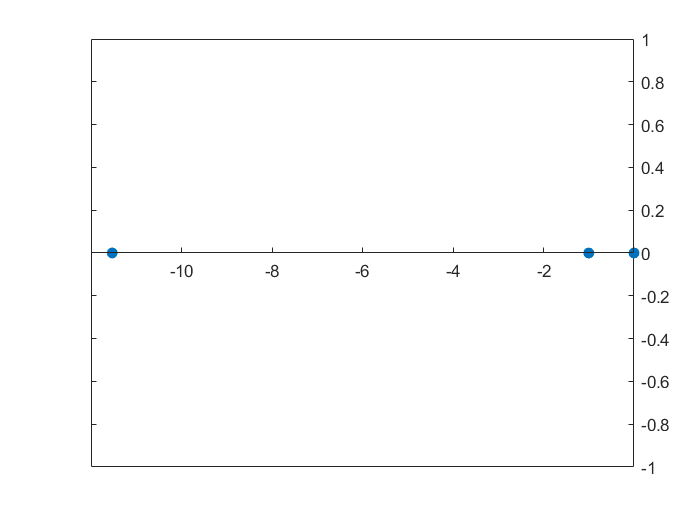


% Plot the poles
stem(real(poles),imag(poles), 'filled')
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

Denoted by the blue dots are the poles of our system.

Having a pole at the origin makes the system critically stable.